# IAVSD23 - Optimizing rail maintenance

## Input data (lookup table for H-index)

clearvars % clear all variables in the workspace

%%% Lookup tables (sheet names in the excel input file)
tonnage = "H_32t";% standard axle load (30 tons), alternatively "H_32t" for heavy axle load (32.5 tons)

%%% Given the axle load, read H-indices in the lookup tables for both MB5 and MB6
[H_table_MB5,H_table_MB6,risk_MB5,risk_MB6] = read_input_data(tonnage);

%%% plot table
% plot_figure('H_table5_heatmap', H_table_MB5);
% plot_figure('H_tables_heatmap', {H_table_MB5, H_table_MB6})

## Interpolation and preprocessing for MB5

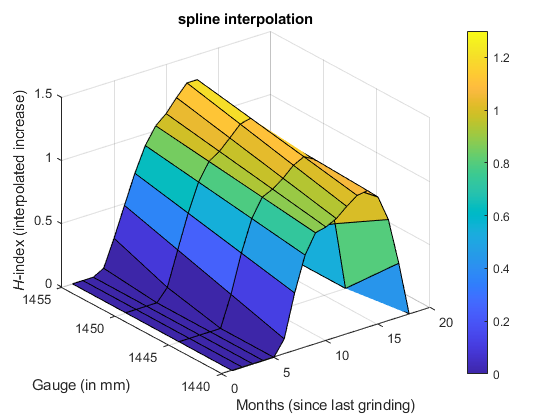

%%% set interpolation method
interpolation_method = 'spline';% alternatively, 'linear', 'makima', 'cubic', or 'spline'

%%% set the maximal frequency for grinding activity
grinding_freq_max = 18; % in months, i.e., max number of months beforing grinding

%%% interpolations of H_table for MB5
H_interpolated_MB5 = interpolation(H_table_MB5,interpolation_method, grinding_freq_max, tonnage);

%%% visualize the interpolated H_tables (and the average monthly deterioration in H-index)
plot_figure(strcat(interpolation_method,' interpolation'), H_interpolated_MB5)


%%% get maximal lifetimes
[max_lifetime_MB5] = get_max_lifetime(risk_MB5);

## Interpolation and preprocessing for MB6

% same interpolation method as for MB6
% same maximal frequency for grinding as for MB6

%%% interpolations of H_table for MB6
rows_to_append = H_table_MB5(1:2, :);
H_table_MB6 = [rows_to_append; H_table_MB6];
H_interpolated_MB6 = interpolation(H_table_MB6,interpolation_method, grinding_freq_max, tonnage);

%%% visualize the interpolated H_tables (and the average monthly deterioration in H-index)
plot_figure(strcat(interpolation_method,' interpolation'), H_interpolated_MB6)

%%% get maximal lifetimes
[max_lifetime_MB6] = get_max_lifetime(risk_MB6);
rows_to_append = max_lifetime_MB5(1:2, :);
max_lifetime_MB6 = [rows_to_append; max_lifetime_MB6];

## LCC Simulation for different maintenance strategies

%%% set the simulation paramters
avg_yearly_gauge_widening = 2; % average yearly gauge widening (in mm/year)
tamping_freq_max = 48; % max number of months before tamping

%%% initializations
months_tamping = 1:tamping_freq_max;
months_grinding = 1:grinding_freq_max;
simulation_LCC_MB5 = zeros(months_grinding(end),months_tamping(end));
rail_lifetime_MB5 = zeros(months_grinding(end),months_tamping(end));
simulation_LCC_MB6 = zeros(months_grinding(end),months_tamping(end));
rail_lifetime_MB6 = zeros(months_grinding(end),months_tamping(end));

%%% find the optimal (LCC-minimal) strategies for tamping and grinding
for grinding_freq=months_grinding % different grinding frequencies
    for tamping_freq=months_tamping % different tamping frequencies
        %%% set strategy
        maint_strategy = [grinding_freq,tamping_freq];
%         maint_strategy = [10,38];
        %%% get optimal for MB5
        [simulation_LCC_MB5(grinding_freq,tamping_freq),rail_lifetime_MB5(grinding_freq,tamping_freq)] = ...
            get_lcc(H_interpolated_MB5, maint_strategy, interpolation_method, "MB5", avg_yearly_gauge_widening, max_lifetime_MB5);
        %%% get optimal for MB6
        [simulation_LCC_MB6(grinding_freq,tamping_freq),rail_lifetime_MB6(grinding_freq,tamping_freq)] = ...
            get_lcc(H_interpolated_MB6, maint_strategy, interpolation_method, "MB6", avg_yearly_gauge_widening, max_lifetime_MB6);
    end
end

## Plot simulation results

% plot results
plot_figure('LCC_heatmap MB5', simulation_LCC_MB5);
[row_grinding,col_tamping] = find(simulation_LCC_MB5==min(simulation_LCC_MB5(:)))
lifetime_MB5 = rail_lifetime_MB5(row_grinding(1), col_tamping(1))
Annuity_MB5 = min(simulation_LCC_MB5(:))
plot_figure('LCC_heatmap MB6', simulation_LCC_MB6);
[row_grinding,col_tamping] = find(simulation_LCC_MB6==min(simulation_LCC_MB6(:)))
lifetime_MB6 = rail_lifetime_MB6(row_grinding(1), col_tamping(1))
Annuity_MB6 = min(simulation_LCC_MB6(:))
% plot_figure('LCC_heatmaps', {simulation_LCC_MB5, simulation_LCC_MB6});